# Exercises 7.2

1. Solve the boundary value problem stated below using the three studied methods of weighted residuals and one basis function

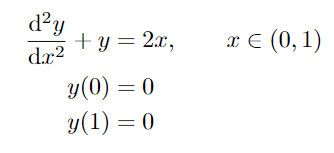

Make a plot with the three approximate functions obtained and a second plot with the three corresponding residual functions.

clear all
clc
syms x

## Weighted Residuals

syms c1
N1 = x*(x-1);
y  = @(x) c1*N1;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
w1 = @(x) 1;
A = int(R(x)*w1(x), 0, 1);
c1 = solve (A, c1);
y  = @(x) c1*N1;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
y1x = y(x)

$$y1x = \frac{6\,x\,\left(x-1\right)}{11}$$

R1x = R(x)

$$R1x = \frac{6\,x\,\left(x-1\right)}{11}-2\,x+\frac{12}{11}$$

## Least squares

syms c1
N1 = x*(x-1);
y  = @(x) c1*N1;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
w1 = diff(R(x),c1);
A = int(R(x)*w1, 0, 1);
c1 = solve (A, c1);
y  = @(x) c1*N1;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
y2x = y(x)

$$y2x = \frac{55\,x\,\left(x-1\right)}{101}$$

R2x = R(x)

$$R2x = \frac{55\,x\,\left(x-1\right)}{101}-2\,x+\frac{110}{101}$$

## Galerkin

syms c1
N1 = x*(x-1);
y  = @(x) c1*N1;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
w1 = N1;
A = int(R(x)*w1, 0, 1);
c1 = solve (A, c1);
y  = @(x) c1*N1;
R  = @(x)diff((y(x)),2) + y(x) - 2*x;
y3x = y(x)

$$y3x = \frac{5\,x\,\left(x-1\right)}{9}$$

R3x = R(x)

$$R3x = \frac{5\,x\,\left(x-1\right)}{9}-2\,x+\frac{10}{9}$$

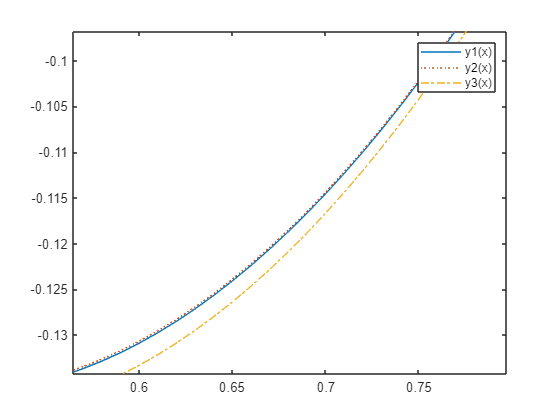

X = 0:0.01:1;
y1 = subs (y1x,x, X);
y2 = subs (y2x,x, X);
y3 = subs (y3x,x, X);
R1 = subs (R1x,x, X);
R2 = subs (R2x,x, X);
R3 = subs (R3x,x, X);
plot(X,y1,'-', X,y2,':', X,y3,'-.')
legend ('y1(x)','y2(x)','y3(x)')

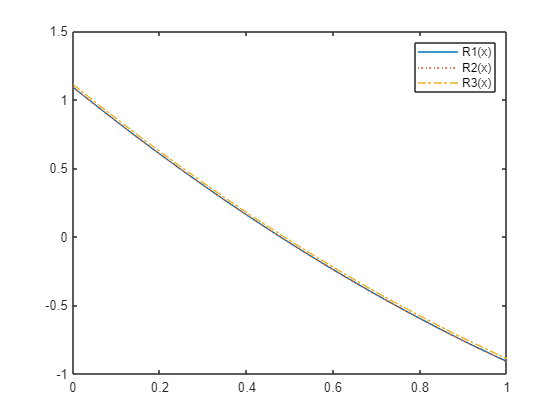

plot(X,R1,'-', X,R2,':', X,R3,'-.')
legend ('R1(x)','R2(x)','R3(x)')